# Simulating the different reward functions and their decay with time

### First, we focus on the change in reward function alone with time. 

Currently,  we sample an exponential decaying function and then add noise to it. 

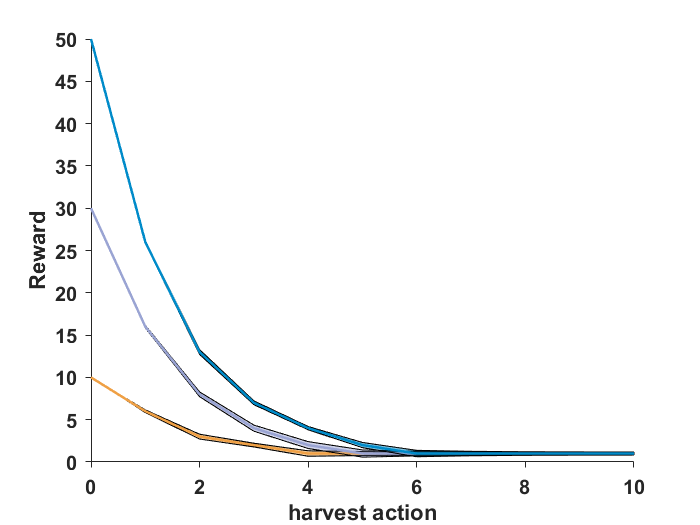

% parameters of reward functions
clf
sd = 1;
beta = 0.5;
alphas = [10,30, 50];
clrs = {[239, 160, 69]/255, [154, 164, 211]/255, [0, 139, 201]/255};

ct = 1:10; % harvest count discrete
cc= 1;

figure,
for alpha =  alphas
    rt_arr = zeros(10000, length(ct)+1);
    for i = 1:10000
        r_t = [alpha, floor(beta.^ct * alpha + max(sd*randn(1,1),1))];
        rt_arr(i,:) = rt_arr(i,:) + r_t;
    end
    rt_arr_cumulative = cumsum(rt_arr,2);
    r_tt = median(rt_arr,1);
    err_tt = std(rt_arr,0,1);
    
    r_ttc = median(rt_arr_cumulative, 1);
    err_ttc = std(rt_arr_cumulative, 0 , 1);
    % plot(ct, r_tt);
    % hold on
    % errorbar(ct, r_tt, err_tt);
    % hold off
    
    figure(1),
    ct_x = [0,ct];
    plot(ct_x, r_tt);
    hold on
    plotsdshading(ct_x,r_tt', err_tt',clrs{cc});
    hold on
    
    figure(2),
    plot(ct_x, r_ttc);
    hold on
    plotsdshading(ct_x,r_ttc', err_ttc',clrs{cc});
    hold on
    cc= cc+1;
end
figure(1)
xlabel('harvest action')
ylabel('Reward')
beautifyfig;

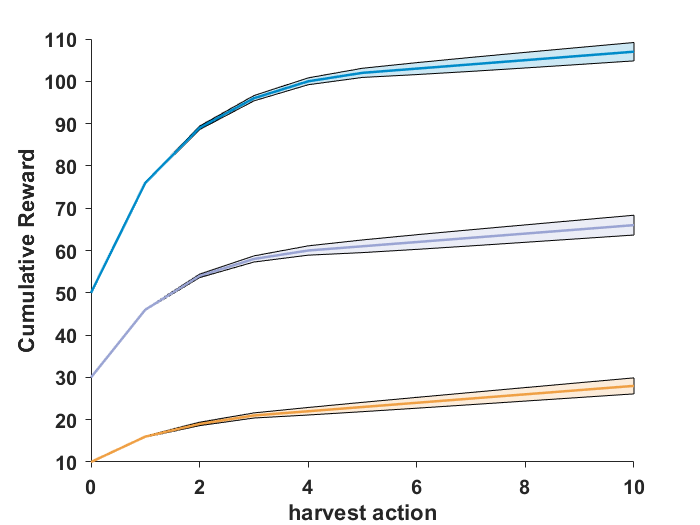

figure(2)
xlabel('harvest action')
ylabel('Cumulative Reward')
beautifyfig;

What if you decay after noising the function? 

r_t = alpha + sd*randn(1,1);
for  c =2:length(ct)
 r_t(end+1) = floor(r_t(c-1)*beta + sd*randn(1,1));    
end

plot(ct, r_t,'r');
hold on

xlabel('harvest action')
ylabel('Reward')

Let us see what  happens with the hyperbolic function in the previous experiment 

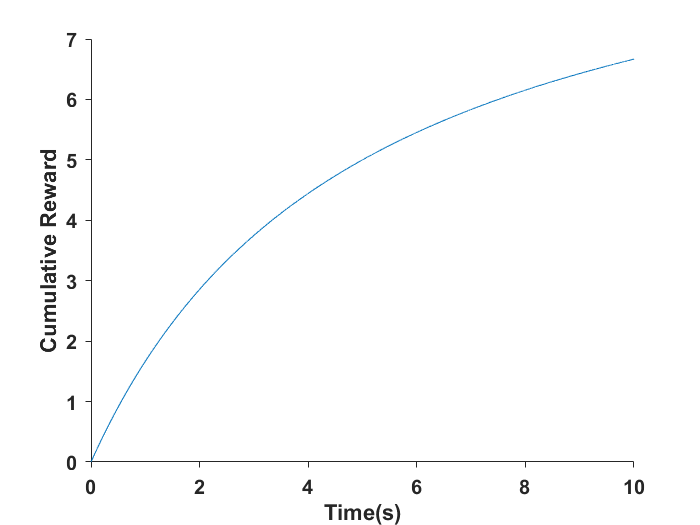

% 
th = 0:0.001:10;
alpha = 10;
beta = 0.2;
r_t = alpha*(1 - 1./(1 + beta*th));

plot(th, r_t)

xlabel('Time(s)')
ylabel('Cumulative Reward')
beautifyfig